clear 
close all
rng(5)

load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data4.mat')
map = Map;
load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map4.mat")
Map = occupancyMap(omap);

Data

RequiredMaps =      100000.00



%Lidar setup
lidar = rangeSensor;
%VFH setup
vfh = controllerVFH;
vfh.UseLidarScan = true;
vfh.SafetyDistance = 0.5;
%vfh.DistanceLimits = [1 2];

%We show it to see our first part
MapFigure = figure;
VFHFigure = figure;
figure(MapFigure);
show(Map)
Map

Map =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.65
            FreeThreshold: 0.20
    ProbabilitySaturation: [0.00 1.00]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.50
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1.00
                 GridSize: [20.00 20.00]
             XLocalLimits: [0 20.00]
             YLocalLimits: [0 20.00]
             XWorldLimits: [0 20.00]
             YWorldLimits: [0 20.00]


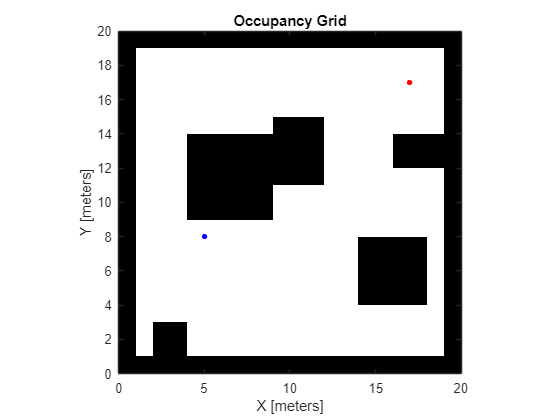

hold on
plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
plot(goal_pose(1), goal_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2, 'Color',"red");


allVFHdata = [];

x = 0;
trigger = true

trigger = logical
   1


test = 100;
counter = 1;
[m,systemview] = memory;
sprintf('%.0f MB',m.MemUsedMATLAB/(1024^2))

ans = '4461 MB'

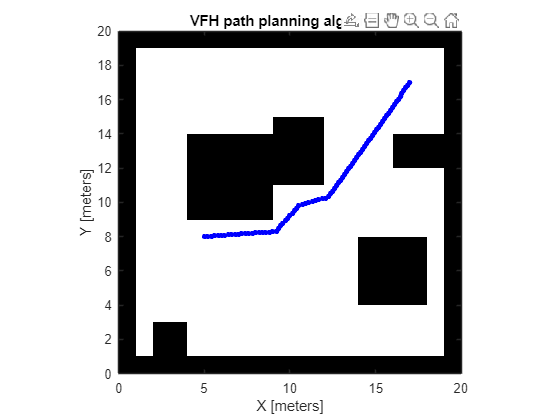

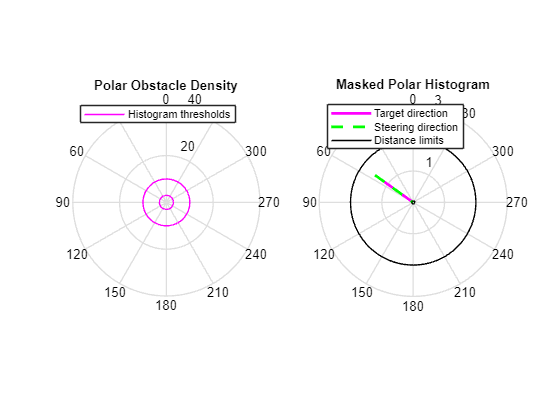

trigger = logical
   0


tic
while trigger
    %Lidar measures
    [ranges,angles] = lidar(robot_pose,Map);


    %Geometry about the angles the be appropriate
    %We calculate the Eucladean distance between the start and end coordinates
    tavolsag_x = goal_pose(1) - robot_pose(1);
    tavolsag_y = goal_pose(2) - robot_pose(2);

    %We use the atan2d to get back the corresponding angle that is in the four
    %quadrant
    goal_angle = atan2d(tavolsag_y,tavolsag_x);
    %We make a correction with the original orientation of the UAV
    goal_angle= deg2rad(goal_angle)+deg2rad(0-start_orientation);
    %We scan the virtual environment
    scan = lidarScan(ranges,angles);
    %We rotate it to be according to the drone orientation
    rotateScan = transformScan(scan,[0,0,robot_pose(3)+deg2rad(0-start_orientation)]);

    %Use the VFH algorithm to calculate the required steering angle in rad
    steeringDir = vfh(rotateScan,goal_angle);
    steeringDir;
    %Convert it to deg
    new_deg = rad2deg(steeringDir);
    figure(VFHFigure)
    show(vfh)
    %Drone parameter setup
    v_drone = 0.2; %m/s [currently be at 0.2, later we can do dynamic adjustments]

    robot_pose(3) = new_deg;
    robot_pose(1) = robot_pose(1)+cosd(new_deg)*v_drone;
    robot_pose(2) = robot_pose(2)+sind(new_deg)*v_drone;
    allVFHdata = [allVFHdata; robot_pose(1), robot_pose(2)];
    figure(MapFigure);
    plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
    %xlabel("X [méter]")
    %ylabel("Y [méter]")
    title("VFH path planning algorithm")
    drawnow
    x = x+1;
    
    if abs(tavolsag_x) < 0.4 && abs(tavolsag_y) < 0.3
        trigger = false
    end

    if counter > test
        break
    end

    counter = counter+1;


end

toc

Elapsed time is 30.476254 seconds.


[m,systemview] = memory;
sprintf('%.0f MB',m.MemUsedMATLAB/(1024^2))

ans = '4490 MB'

allVFHdata

allVFHdata =           5.20          8.01
          5.40          8.03
          5.60          8.04
          5.80          8.06
          6.00          8.07
          6.20          8.09
          6.40          8.10
          6.60          8.11
          6.80          8.13
          6.99          8.14
